# 03F. Separatrix

## Mingyang Lu

## 1/7/2024

## Vector field

X_all = 0:20:600;  % all X grids
Y_all = 0:20:650;  % all Y grids
[X_all, Y_all] = meshgrid(X_all, Y_all);  % all combinations of X and Y
XY_all = [X_all(:), Y_all(:)];  % reshape the array into a 2D array with 2 columns

% Apply the function along the specified axis
results_unit = zeros(size(XY_all, 1), 4);
for i = 1:size(XY_all, 1)
    results_unit(i, :) = generate_normalized_vector_field(@derivs_ts, ...
        XY_all(i, :), 20);
end

figure('Units', 'inches', 'Position', [0, 0, 5, 5]);
quiver(results_unit(:, 1), results_unit(:, 2), ...
    results_unit(:, 3), results_unit(:, 4), ...
    0, 'Color', 'black', 'LineWidth', 1.2);

xlabel('X');
ylabel('Y');
axis equal;
grid on;
hold on;

### Simulation to obtain separatrix

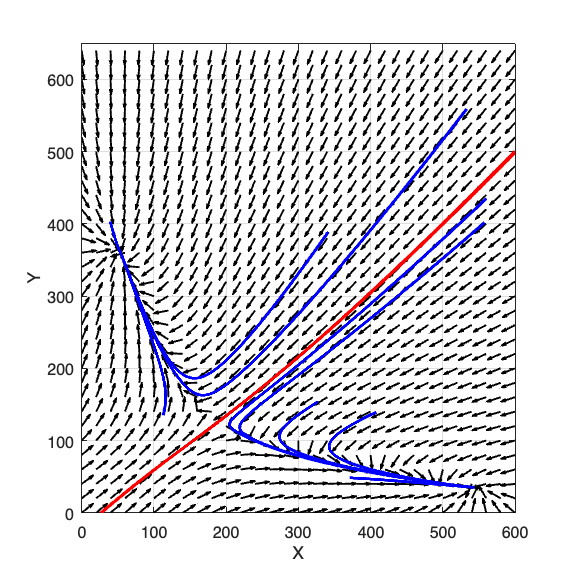

rng(75);  % Set the seed for the random number generator
t_total = 100;
dt = 0.01;
X_range = [0, 600];
Y_range = [0, 650];

% Simulations of the original system
X_init_1 = rand(10, 2) * 600;
for i = 1:size(X_init_1, 1)
    results = RK4_generic(@derivs_ts, X_init_1(i, :), t_total, dt);
    plot(results(:, 2), results(:, 3), 'Color', 'blue','LineWidth', 2);
    hold on;
end

% Simulation to find separatrix
X_init_2 = rand(10, 2) * 2 - 1;
X_init_2(:, 1) = X_init_2(:, 1) + 189.96888;
X_init_2(:, 2) = X_init_2(:, 2) + 126.64398;
for i = 1:size(X_init_2, 1)
    results = RK4_generic(@derivs_ts_revised, X_init_2(i, :), t_total, dt);
    results = results(...
        (results(:, 2) > X_range(1)) & (results(:, 2) < X_range(2)) & ...
        (results(:, 3) > Y_range(1)) & (results(:, 3) < Y_range(2)), :);
    plot(results(:, 2), results(:, 3), 'Color', 'red','LineWidth', 2);
    hold on;
end

xlabel("X");
ylabel("Y");
xlim([0, 600]);
ylim([0, 650]);
hold off;

### Define MATLAB functions

1. Inhibitory Hill function

function out = hill_inh(a, X_th, n)
    out = 1 ./ (1 + (a ./ X_th).^n);
end

2. Derivative function for a toggle switch circuit

function result = derivs_ts(t, Xs)
    X = Xs(1);
    Y = Xs(2);
   
    dxdt = 5 + 50 * hill_inh(Y, 100, 4) - 0.1 * X;
    dydt = 4 + 40 * hill_inh(X, 150, 4) - 0.12 * Y;
    
    result = [dxdt, dydt];
end

3. RK4 ODE integrator for a multiple-variable system.

function results = RK4_generic(derivs, X0, t_total, dt, varargin)
    % 4th order Runge-Kutta (RK4) for a generic multi-variable system
    % derivs: the function of the derivatives
    % X0: initial condition, a list of multiple variables
    % t_total: total simulation time, assuming t starts from 0 at the beginning
    % dt: time step size
    t_all = 0:dt:t_total;
    n_all = length(t_all);
    nx = length(X0);
    X_all = zeros(n_all, nx);
    X_all(1, :) = X0;
    for i = 1:(n_all - 1)
        t_0 = t_all(i);
        t_0_5 = t_0 + 0.5 * dt;
        t_1 = t_0 + dt;
        k1 = dt * derivs(t_0, X_all(i, :), varargin{:});
        k2 = dt * derivs(t_0_5, X_all(i, :) + k1 / 2, varargin{:});
        k3 = dt * derivs(t_0_5, X_all(i, :) + k2 / 2, varargin{:});
        k4 = dt * derivs(t_1, X_all(i, :) + k3, varargin{:});
        X_all(i + 1, :) = X_all(i, :) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    end
    results = [t_all', X_all];
end

4. Generate unit vector field

% Define function to generate normalized vector field
function vector = generate_normalized_vector_field(derivs, Xs, scale)
    df = derivs(0, Xs);
    df_norm = scale * df/norm(df);
    vector = [Xs, df_norm];
end

5. Inverse of the toggle switch derivatives

function result = derivs_ts_revised(t, Xs)
    X = Xs(1);
    Y = Xs(2);
   
    dxdt = -(5 + 50 * hill_inh(Y, 100, 4) - 0.1 * X);
    dydt = -(4 + 40 * hill_inh(X, 150, 4) - 0.12 * Y);
    
    result = [dxdt, dydt];
end